Now we try volume Bragg diffraction grating equation:

gp=1000;
theta=0:1:64;
order=1;
lambda1=2*gp*sind(theta)/order;
figure

order=2;
lambda2=2*gp*sind(theta)/order;
figure

order=3;
lambda3=2*gp*sind(theta)/order;
figure


Effect of grating periodicity

lambda=350:1:750;
n_polymer=1.5227;
n_glass=1.458;
FF_1=100/1070;
gp=1070;
n_ave1=(((gp-100)/gp)*1)+((100/gp)*n_polymer);
n_ave2=(((gp-100)/gp)*1)+((100/gp)*n_polymer);
m_r=zeros(9,401);
for i=1:401
    for j=-4:4 
        if -j*lambda(i)/gp/n_glass>=-1
            if -j*lambda(i)/gp/n_glass<=1
                m_r(j+5,i)=j;
            else
            end
        else
        end
    end
end
m_t=zeros(7,401);
for i=1:401
    for j=-4:4
        if -j*lambda(i)/gp/n_ave2>=-1
            if -j*lambda(i)/gp/n_ave2<=1
                m_t(j+5,i)=j;
            else
            end
        else
        end
    end
end



ans = 3.1201e+03

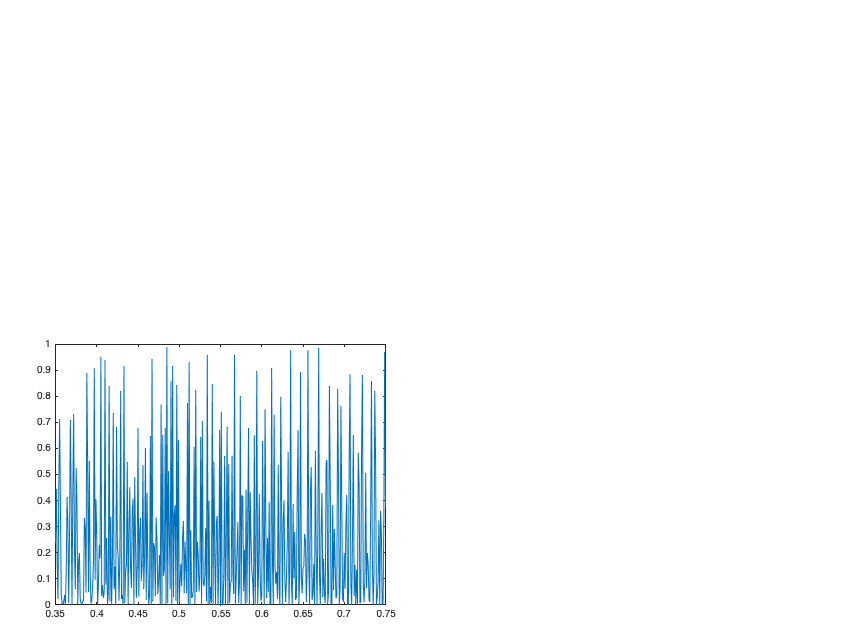

lambda=0.350:0.001:0.750;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=1070;
n_ave1=(((gp-100)/gp)*1)+(n_lambda.*(100/gp));
n_ave2=(((gp-180)/gp)*1)+(n_lambda.*(180/gp));
delta_n1=(n_lambda-1)/2;
delta_n2=(n_lambda-1)/2;

d2=(903.68-381.66)/1000; %thickness of each layer
d1=381.66/1000;

theta1=0; %incident angles on each layer
theta2=0;

eta_p1=((sin((pi.*delta_n1.*d1)./(lambda*cos(theta1))*cos(2*theta1))).^2);
eta_s1=((sin((pi.*delta_n1.*d1)./(lambda*cos(theta1)))).^2);
eta_unpolarized1=0.5*eta_p1+0.5*eta_s1;
eta_p2=((sin((pi.*delta_n2.*d2)./(lambda*cos(theta2))*cos(2*theta2))).^2);
eta_s2=((sin((pi.*delta_n2.*d2)./(lambda*cos(theta2)))).^2);
eta_unpolarized2=0.5*eta_p2+0.5*eta_s2;

eta_0=eta_p1.*eta_s2;
eta_45=eta_unpolarized1.*eta_unpolarized2;
eta_90=eta_s1.*eta_p2;

plot(lambda,eta_0)